# Airframe Model -  Parametric Displays and Flat Earth Coordinates

## Topic

This LiveScript continues with the development of your lesson on Airframes and discusses the standard Flat-Earth inertial reference frame and a useful and standard way of parametrically displaying your state output.

## Motivation

You will find it helpful to begin to plot the output of your state-space models in a standard way, to capture useful technial detail and to easily transition to more advanced Simulink models in the future.   You will develop one set of standard outputs here.

## Learning Objective

In this module you will learn how to create a set of parametric displays which give specific quantitative measures of each of the state space variables.   In particular, you will create a set of parametric traces of each variable, as a function of time.    This approach will resemble closely what you will see in the development of your Simulink models.

## Lesson

### Utilities Used in Lesson

clear;
addpath('utils');
params=sys_params;

### Options for Display of Output

In your prior modules you have seen output of your simulations displayed in an x-y-z plot as time evolves.    The output of the system was this 3-D rendering provided to you for illustrative purposes.  Next, you will see the same data plotted with each of the state space variables displayed on a common chart.   The first approach is quite visual and great for developing an intuition of what is happening physically.  The second has more useful quantitative information.   

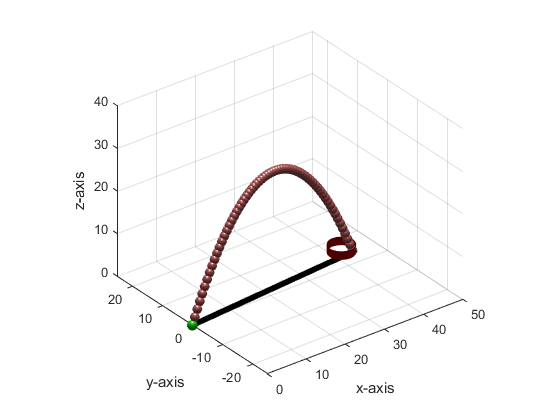

% Shooter

phid    =   5;    % angle from x-z plane ranging from -90 to +90 degrees
thetad  = 68  ;       % angle from x-y plane ranging from -90 to +90 degrees
v0      =  25;         % initial velocity (m/s)
tmax    =  5;         % duration of flight
z0=[0;0;0];
phi0=phid*pi/180;  theta0=thetad*pi/180;
projectileShooting(@fm,phi0,theta0,v0,tmax);

### Output Plots - Parametric Traces of State (functions of time)

An alternative set of plots is suggested below.   You can see in the following figures the components of position plotted as a function of time.    The force of gravity on effects the motion in the z-axis.   The constant acceleration results in a parabolic path in z, which eventually hits the ground (at approximately t=4.75 seconds, when z=0).

It is important for you to understand how to read these plots as eventually you will be using scopes in Simulink and the default display on the scope shows results in this way.

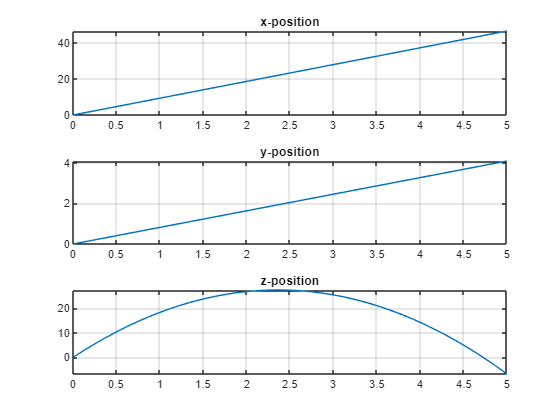

[ts,xs]=fm(phi0,theta0,z0,v0,tmax);
figure
tiledlayout(3,1)
nexttile
plot(ts,xs(1,:)); grid on;title('x-position'); 
nexttile
plot(ts,xs(2,:));grid on;title('y-position')
nexttile
plot(ts,xs(3,:));grid on;title('z-position')

### Flat Earth Reference Frame

The inertial reference frame that you will use throughout the remaining modules in the "Flat Earth Reference Frame".   This is one of the standard reference frames used within the UAV community.  You can read more about it in the MATLAB help for "6DOF".   The flat Earth reference frame is considered inertial, an excellent approximation that allows the forces due to the Earth motion relative to the "fixed stars" to be neglected.

The interesting thing about the flat Earth reference frame that you need to remember is that the z-axis is pointed down.  

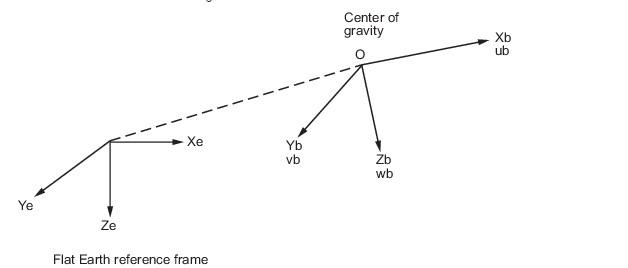

In the previous lessons, you defined a cartesian reference frame with the z-axis pointed up and with the gravity vector pointed down.   While that satisfied your intuition with "up" being positive z, **you** **need to change** this now to conform with the standard and the remaining modules.

#### Gravity

In the flat earth reference frame, gravity creates a force on your UAV which, in the flat Earth reference frame, points in the positive ${\hat{a} }_z$ direction.

The gravitational force in your model is represented in the vector  and so, the sign of this force needs to change.   Likewise, you need to pay attention to angle measured from the z-axis, so that you get it right.

The equations become:


$$x\left(t\right)=x_0 +v_{x,0} \;t$$



$$y\left(t\right)=y_0 +v_{y,0} \;t$$



$$z\left(t\right)=z_0 +v_{z,0} \;t+\frac{1}{2}gt^2$$


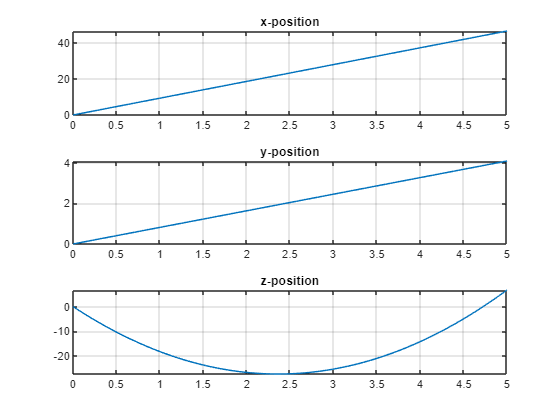

phid    =   5;    % angle from x-z plane ranging from -90 to +90 degrees
thetad  = -68  ;       % angle from x-y plane ranging from -90 to +90 degrees
v0      =  25;         % initial velocity (m/s)
tmax    =  5;         % duration of flight
z0=[0;0;0];
phi0=phid*pi/180;  theta0=thetad*pi/180;

[ts,xs]=fm2(phi0,theta0,z0,v0,tmax);
figure
tiledlayout(3,1)
nexttile
plot(ts,xs(1,:)); grid on;title('x-position'); 
nexttile
plot(ts,xs(2,:));grid on;title('y-position')
nexttile
plot(ts,xs(3,:));grid on;title('z-position')

## Exercise